%%%%%%%%%%%%%%
% Attachment quantification v2
% Inspired by Julia Schwartzman
% Written by Elise Ledieu
% Date of First Version: 2020 07 22
% Date of Second Version: 2021 01 30
% Date of Third Version: 2021 04 05
%%%%%%%%%%%%%%%

## Reset the workspace

clear all;
close all;

## Defining Parameters

%define a directory in which to put renamed images and outputs
output_directory='/Volumes/EliseWork/20210811Facilitation/out';
%read in .tif stacks in directory
myFolder = '/Volumes/EliseWork/20210811Facilitation';

## Renaming Files - to enhance readability

filePattern = fullfile(myFolder, '**', '*.tif*'); %selects files with .tif extension
theFiles = dir(filePattern);
for k = 1 : length(theFiles) %goes through all the files that are .tif
    baseFileName = theFiles(k).name;
    folderFileName = theFiles(k).folder;
    FullFileName = fullfile(folderFileName, baseFileName);
    image=imread(FullFileName);
    newname = strcat(baseFileName(1:end-40),'.tif'); %removes the last 40 characters of the file name
    fullDestinationFileName = fullfile(output_directory, newname);
    imwrite(image,fullDestinationFileName,'tif'); %Saves a new image in the output directory
end

## Sampling images to verify the different thresholds

filePattern = fullfile(output_directory, '*.tif'); %selects files with .tif extension
theFiles = dir(filePattern);

a =150; % can be changed <- index to select an image to manually check the imaging pipeline

baseFileName = theFiles(a).name;
fullFileName = fullfile(output_directory, baseFileName);
fprintf(1, 'Now reading %s\n', fullFileName); %Allows to read the conditions selected

Now reading /Volumes/EliseWork/20210811Facilitation/out/SE400_C03_s13.tif


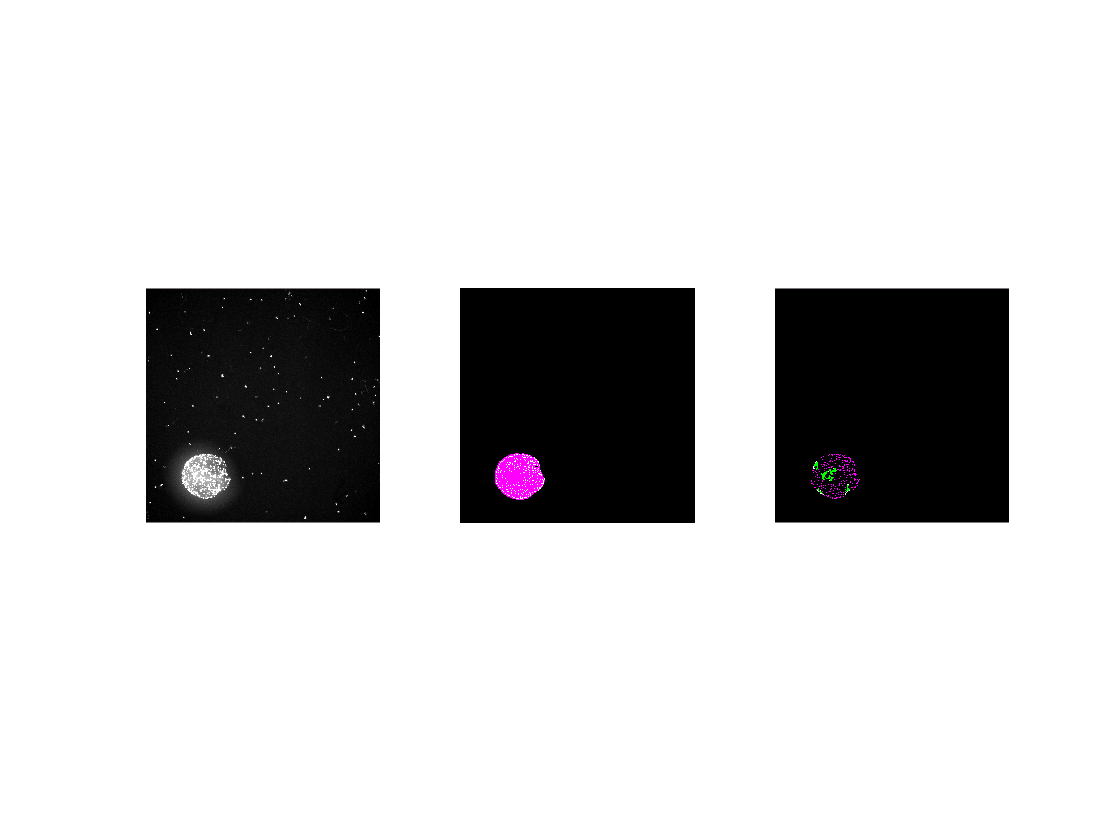


%%Imaging Parameters
Neigh_size = 5; %Neighborhood size for gaussian filter to find bacteria *KEY PARAMETER*


%Initializes Beaconout
beaconout = struct('Area',NaN, 'AreaWSat', NaN,'cells_total_Area',NaN,'cells_number_patches',NaN,'well',NaN);

signal = imread(fullFileName); %Read image
signal = imadjust(signal); %Enhances contrast

%%Detects Beads
signal_mask=imgaussfilt(signal,10); %Blurs the background to avoid small noise to be in
maskb = imbinarize(signal_mask); %Binarizes the image
maskb = imfill( maskb ,'holes'); %Removes potentially holes that got through
beads = bwlabel(maskb); % Makes the bead mask binary

% %Creates a mask with adaptive thresholding to find bacteria
signal_cell = imgaussfilt(signal,2);
T = adaptthresh(signal_cell, 'Statistic', 'gaussian', 'NeighborhoodSize', Neigh_size); %The Neighborhood Size matters a lot here
signal_cell = imbinarize(signal_cell,T);
signal_cell = double(beads>0).*double(signal_cell); %Subselects cells that are on beads

% % Creates a mask removing the part that are saturated due to bead halo - aka where the signal to noise is not great
sat = (signal== 65535); %Gets the saturated pixels
sat = imfill( sat ,'holes');  %Fills potential holes within a saturated area
sat_area = bwlabel(sat);
stats= regionprops(sat_area,'Area');
for i = 1:length(stats)
    junk=stats(i);
    if junk.Area <1000
        sat_area(sat_area==i)=0;
    end
end
sat_area = (sat_area >0);

%Finds cells for each bead and record statistics
for f = 1:max(max(beads)) %Loop on all the detected beads
    if sum(sum(beads==f))>8000 %Removes objects that are too small to be beads 
        bead = double(beads==f).* double(1-sat_area); % Removes the saturated area from the identified beads
        
        beaconout(end+1).Area = sum(sum(bead)); % Area of the bead without saturation
        beaconout(end).AreaWSat = sum(sum(beads==f)); %Area of the bead with saturated pixek
        
        cells= bead.*double(signal_cell); %Threshold applied only on the cells which are on the bead
        cells = bwlabel(cells); %Cells on Bead given the top hat method
    
        cellsstats= regionprops(logical(cells),'Area'); %Creates a list of objects, each corresponding to one cell
        cells_total_Area= sum(struct2array( cellsstats )); %Calculates the total Area of cells on the bead
        cells_number_patches = length(cellsstats);
        beaconout(end).cells_total_Area = cells_total_Area;
        beaconout(end).cells_number_patches = cells_number_patches; 
        beaconout(end).well = baseFileName(1:end-4);
    end
    
end


C = imfuse(signal_cell,beads);
Ca = imfuse(sat_area,signal_cell);
figure(2)
subplot(1,3,1)
imshow(signal) %Shows the original image with enhanced contrast
subplot(1,3,2)
imshow(C) %Bead area in pink and cells in green
subplot(1,3,3)
imshow(Ca) %Saturated area in green and cells in pink <- normally there is no overlap between the two

## Detect Beads, Cells and output statistics

filePattern = fullfile(output_directory, '*.tif');
theFiles = dir(filePattern);
beaconout = struct('Area',NaN, 'AreaWSat', NaN,'cells_total_Area',NaN,'cells_number_patches',NaN,'well',NaN);

for a = 1 : length(theFiles)
    baseFileName = theFiles(a).name;
    fullFileName = fullfile(output_directory, baseFileName);
    fprintf(1, 'Now reading %s\n', fullFileName);
    signal = imread(fullFileName); %Read image
    signal = imadjust(signal); %Adjust image contrast

    %%Detects Beads
    signal_mask=imgaussfilt(signal,10); %Blurs the background to avoid small noise to be in
    maskb = imbinarize(signal_mask); %Binarizes the image
    maskb = imfill( maskb ,'holes'); %Removes potentially holes that got through
    beads = bwlabel(maskb); % Makes the bead mask binary
    
    % %Creates a mask with adaptive thresholding to find bacteria
    signal_cell = imgaussfilt(signal,2); %Filters out small noises (smaller than a cell)
    T = adaptthresh(signal_cell, 'Statistic', 'gaussian', 'NeighborhoodSize', Neigh_size); %Creates a Gaussian adaptive threshold. The Neighborhood Size matters a lot here
    signal_cell = imbinarize(signal_cell,T); %Binarizes through the aforementioned threshold
    signal_cell = double(beads>0).*double(signal_cell); %Keeps only the cells that are on beads
    
    % % Creates a mask removing the part that are saturated due to bead halo - aka where the signal is not great
    sat = (signal== 65535); %Gets the saturated pixels
    sat = imfill( sat ,'holes'); %Fills potential holes within a saturated area
    sat_area = bwlabel(sat);
    stats= regionprops(sat_area,'Area'); 
    for i = 1:length(stats)
        junk=stats(i);
        if junk.Area <8000 %Selects the areas that are too big to be bacteria. There shouldn't be colonies at the stage of colonization I am looking at. Leaves some room for potential high colonization.
            sat_area(sat_area==i)=0;
        end
    end
    sat_area = (sat_area >0); 
    
    %Find cells for each bead and record statistics
    for f = 1:max(max(beads)) %Loop on all the detected beads
        if sum(sum(beads==f))>8000 %Only keeps the beads that are bigger than the threshold
            bead = double(beads==f).* double(1-sat_area);
            
            beaconout(end+1).Area = sum(sum(bead));
            beaconout(end).AreaWSat = sum(sum(beads==f));
            
            cells= bead.*double(signal_cell); %Threshold applied only on the cells which are on the bead
            cells = bwlabel(cells); %Cells on Bead given the top hat method
            
            cellsstats= regionprops(logical(cells),'Area');
            cells_total_Area= sum(struct2array( cellsstats ));
            cells_number_patches = length(cellsstats);
            beaconout(end).cells_total_Area = cells_total_Area;
            beaconout(end).cells_number_patches = cells_number_patches;
            beaconout(end).well = baseFileName(1:end-4);
        end
        
    end
    
end

Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s1.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s2.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s3.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s4.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s5.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s6.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E04_F02_s7.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s1.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s10.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s11.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s12.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s13.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s14.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s2.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s3.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s4.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s5.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s6.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s7.tif


Now reading /Volumes/EliseWork/20210811Facilitation/out/E400_C02_s8.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s16.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s17.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s18.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s19.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s2.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s20.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s21.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s3.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s4.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s5.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s6.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s7.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s8.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E400_E04_s9.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s1.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s10.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s11.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s12.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s2.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s3.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s4.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s5.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s6.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s7.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s8.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E40_E05_s9.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s1.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s10.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s11.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s12.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s13.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s14.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s15.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s2.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s3.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s4.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s5.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s6.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s7.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s8.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8E4_E06_s9.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s1.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s10.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s2.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s3.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s4.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s5.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s6.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s7.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s8.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E02_s9.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s1.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s2.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s3.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s4.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s5.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s6.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s7.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s8.tif


Now reading /Volumes/EliseWork/20210730Facilitation/out/20210730Facilitation 18h-S8_E08_s9.tif



beaconout( all( cell2mat( arrayfun( @(x) structfun( @(a)isscalar(a)&&isnan(a), x ), beaconout, 'UniformOutput', false ) ), 1 ) ) = [];
writetable(struct2table(beaconout),strcat(output_directory,'/20210811Out.csv')) %Creates a CSV with all the information collected